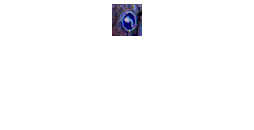

I = readimg(34, 5, 5);

I = preprocess(I);
imshow(I)

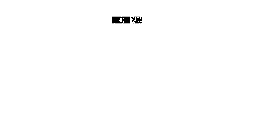


displayChannels(I);

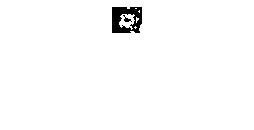


colors = splitColor(I);

height = size(I,1);
width = size(I, 2);

newWidth = int16(rp.MajorAxisLength/rp.MinorAxisLength * width);

stretched = imresize(I,[height, newWidth]);

blue = imresize(colors(:,:,2),[height, newWidth]);

blue = imopen(blue,strel('disk', 1));

imshow(blue);

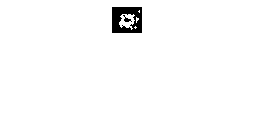


blue = imclearborder(blue,4);

imshow(blue);

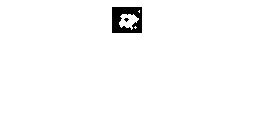


blue = imclose(blue,strel('disk', 2));

imshow(blue);

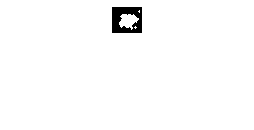


blue = imfill(blue, 'holes');

imshow(blue);

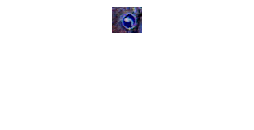


blue = bwareafilt(blue,1);

rp = regionprops(blue, 'all');

imshow(stretched);


Rmin = int8(size(blue,1)/4);
Rmax = int8(size(blue,1)/2);

imshow(stretched);


[centersBright, radiiBright] = imfindcircles(blue,[Rmin Rmax],'ObjectPolarity','bright','Sensitivity',0.9);
viscircles(centersBright, radiiBright,'Color','b');